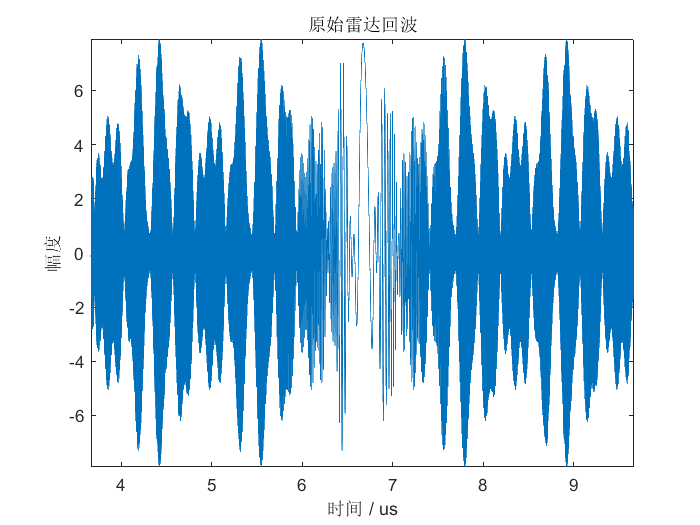

clear;clc; close all;
%%参数设置
c=3e8;%光速
f0=5.321e9;%载频
B=400e6;%信号调制带宽
Tp=6e-6;%信号持续带宽（脉冲宽度6us）
alpha=2*B/Tp;%调频率
fs=6*B;%设置采样率
Ts=1/fs;%采样间隔
N=round(Tp/Ts);%采样点数
%%设置目标参数
R=[995,1000,1001,1005];%目标距离
RCS=[1 1.5 2.25 3.375];%目标有效面积（反射系数）
M=length(R);%目标个数
R0=mean(R);%设置参考中心距离（用于保证目标在一个回波探测范围内
Rwid=Tp*c/2;%能够观察到的最大距离范围
Rmax=floor(R0+Rwid/2);%观察目标距离雷达的最远距离
Rmin=floor(R0-Rwid/2);%观察目标距离雷达的最近距离
%% 脉冲压缩
t0=linspace(-Tp/2,Tp/2,N);%复制发射信号
St=exp(1j*pi*alpha*t0.^2);%发射的LFM信号
%%回波
t=linspace(2*Rmin/c,2*Rmax/c,N);
td = ones(M,1)*t-2*R'/c*ones(1,N);
Srt=RCS*(   exp(1j*pi*alpha*td.^2) .*(abs(td)<Tp/2)  );
%% 匹配滤波
Nfft = 2^nextpow2(N+N-1);
Srw=fft(Srt,Nfft);%对回波信号求FFT
Sw=conj(fft(St,Nfft));
Sout =fftshift(ifft(Srw.*Sw));%匹配滤波结果
N0 =(Nfft-N)/2;
Z=abs(Sout(N0 :(N0+N-1)));
Z = Z/max(Z);%归一化
ZdB =db(Z);
%% 绘图
figure,plot(t*1e6,real(Srt));
axis tight
xlabel('时间 / us');ylabel("幅度");title("原始雷达回波")

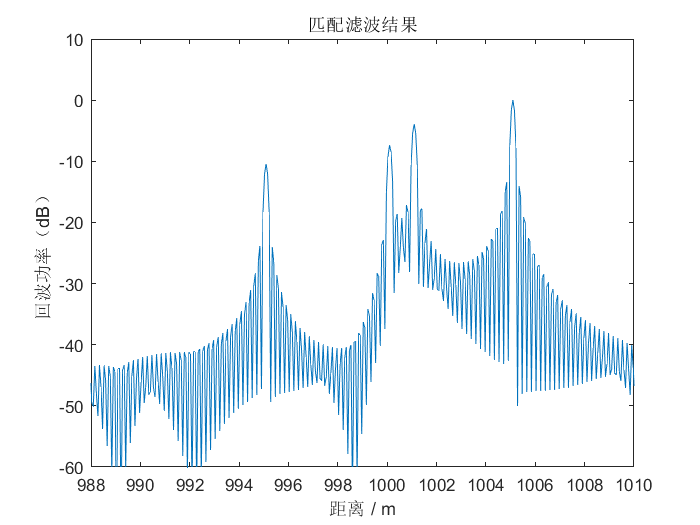

figure,plot(t*c/2,ZdB);
%axis([950,1050,-60,10]);%B=40e6
axis([988,1010,-60,10]);%B=400e6
xlabel('距离 / m');ylabel("回波功率（dB）");title("匹配滤波结果")